load('Assignment_Data_SC42145.mat'); 
sys = ss(A, B, C, D);

sys_min = minreal(sys,0.00001);

[num, den] = ss2tf(A, B, C, D, 1); 
siso_sys = sys_min(1,1);
siso_sys = -siso_sys;
[GM, PM, Wcg, Wcp] = margin(siso_sys); 
disp(['Gain Margin (dB): ', num2str(20*log10(GM))]);

Gain Margin (dB): 24.1957


disp(['Phase Margin (degrees): ', num2str(PM)]);

Phase Margin (degrees): Inf


disp(['Gain Crossover Frequency (rad/s): ', num2str(Wcg)]);

Gain Crossover Frequency (rad/s): 0.19937


disp(['Phase Crossover Frequency (rad/s): ', num2str(Wcp)]);

Phase Crossover Frequency (rad/s): NaN


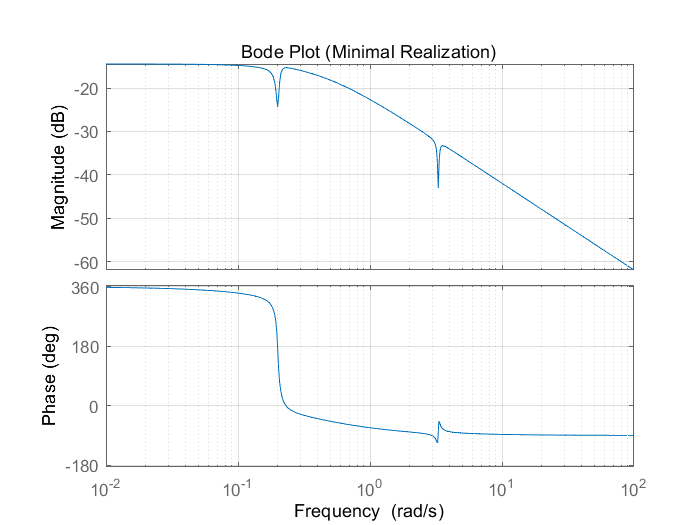

figure;
bode(siso_sys);
grid on;
title('Bode Plot (Minimal Realization)');

[mag, phase, omega] = bode(siso_sys);
mag = squeeze(mag); 
omega = squeeze(omega); 
mag_db = 20*log10(mag); 
index_3db = find(mag_db <= -3, 1, 'first'); 
bw = omega(index_3db);
disp(['Bandwidth: ', num2str(bw), ' rad/s']);

Bandwidth: 0.01 rad/s


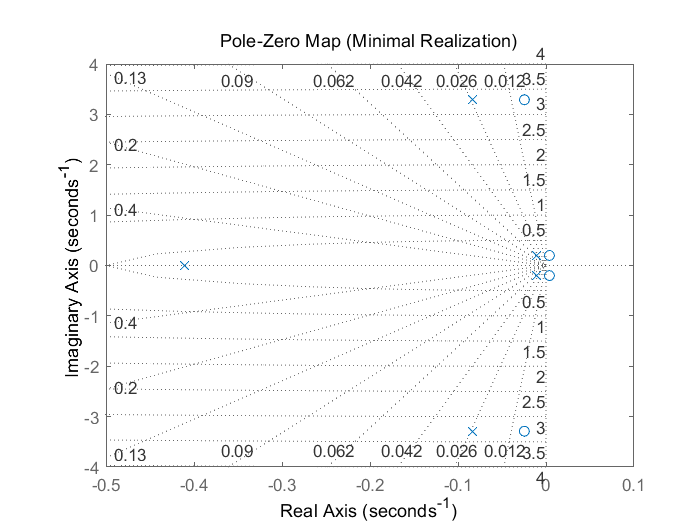

figure;
pzmap(siso_sys);
grid on;
title('Pole-Zero Map (Minimal Realization)');


Kp = 0.25; 
Ki = 0.49; 
Kd = 8.1; 
Tf = 1; 
pid_controller = Kp + tf([0 Ki], [1 0]) + tf([Kd 0], [Tf 1]);

wn1 = 0.1996; 
zeta_n1 = 0.05248; 
zeta_d1 = 0.01925; 
anti_notch1 = tf([1, 2*zeta_n1*wn1, wn1^2], [1, 2*zeta_d1*wn1, wn1^2]);

wn2 = 3.2878; 
zeta_n2 = 0.02529; 
zeta_d2 = 0.00748; 
anti_notch2 = tf([1, 2*zeta_n2*wn2, wn2^2], [1, 2*zeta_d2*wn2, wn2^2]);

anti_notch_combined = series(anti_notch1, anti_notch2);

open_loop = anti_notch_combined * pid_controller * siso_sys;
closed_loop = feedback(open_loop, 1);

[GM, PM, Wcg, Wcp] = margin(open_loop);
disp(['Gain Margin (dB): ', num2str(20*log10(GM))]);

Gain Margin (dB): 14.7499


disp(['Phase Margin (degrees): ', num2str(PM)]);

Phase Margin (degrees): 79.987


disp(['Gain Crossover Frequency (rad/s): ', num2str(Wcg)]);

Gain Crossover Frequency (rad/s): 0.19704


disp(['Phase Crossover Frequency (rad/s): ', num2str(Wcp)]);

Phase Crossover Frequency (rad/s): 0.080949



[mag, ~, omega] = bode(open_loop);
mag = squeeze(mag);
omega = squeeze(omega);
mag_db = 20*log10(mag);
index_bw = find(mag_db <= -3, 1, 'first'); 
bw = omega(index_bw);
disp(['Bandwidth: ', num2str(bw), ' rad/s']);

Bandwidth: 0.10966 rad/s


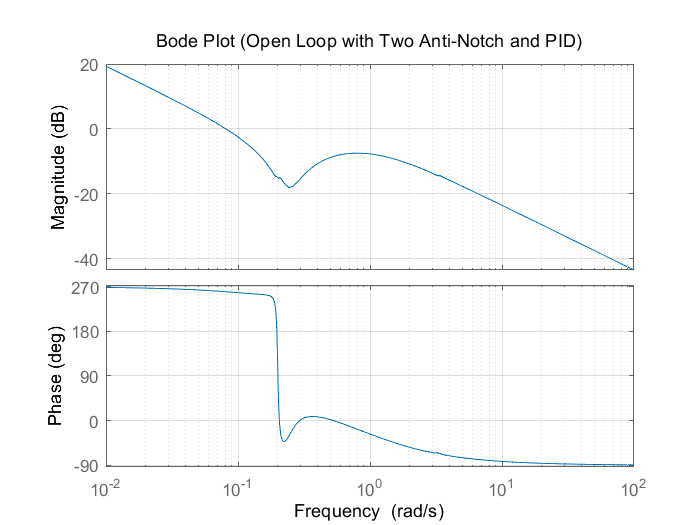


figure;
bode(open_loop);
grid on;
title('Bode Plot (Open Loop with Two Anti-Notch and PID)');

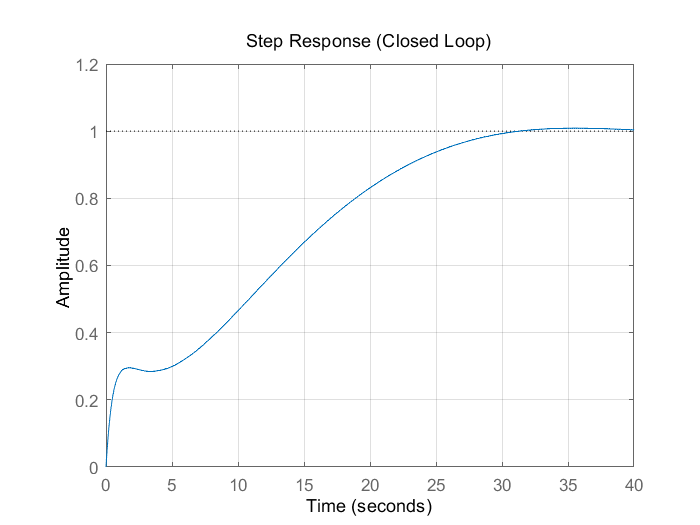


figure;
step(closed_loop);
grid on;
title('Step Response (Closed Loop)');

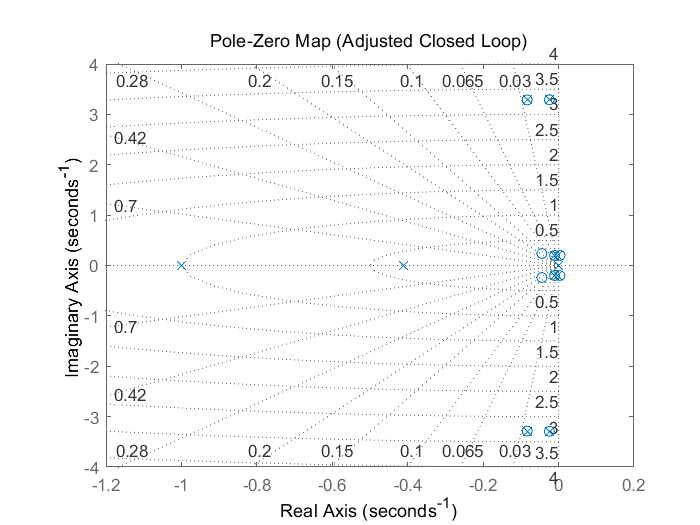


figure;
pzmap(open_loop);
grid on;
title('Pole-Zero Map (Adjusted Closed Loop)');


info = stepinfo(closed_loop);
disp(['Settling Time: ', num2str(info.SettlingTime), ' seconds']);

Settling Time: 28.3666 seconds


disp(['Overshoot: ', num2str(info.Overshoot), ' %']);

Overshoot: 0.89067 %


steady_state_value = dcgain(closed_loop); 
steady_state_error = abs(1 - steady_state_value); 
disp(['Steady-State Error: ', num2str(steady_state_error)]);

Steady-State Error: 0


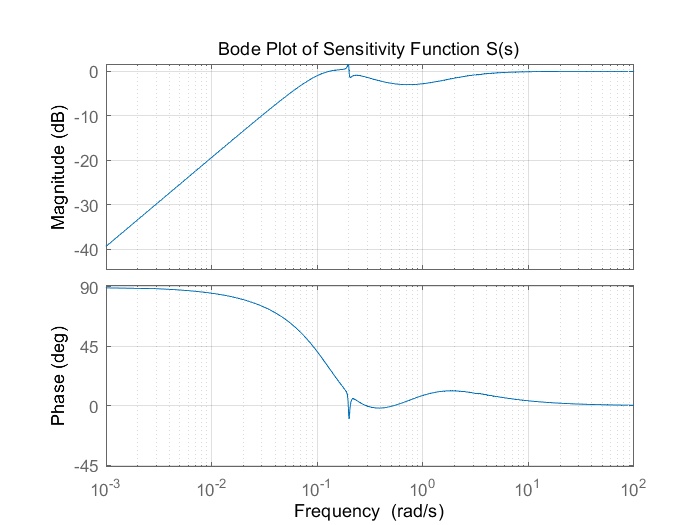


sensitivity_function = 1 / (1 + open_loop);

complementary_sensitivity_function = open_loop / (1 + open_loop);

figure;
bode(sensitivity_function);
grid on;
title('Bode Plot of Sensitivity Function S(s)');

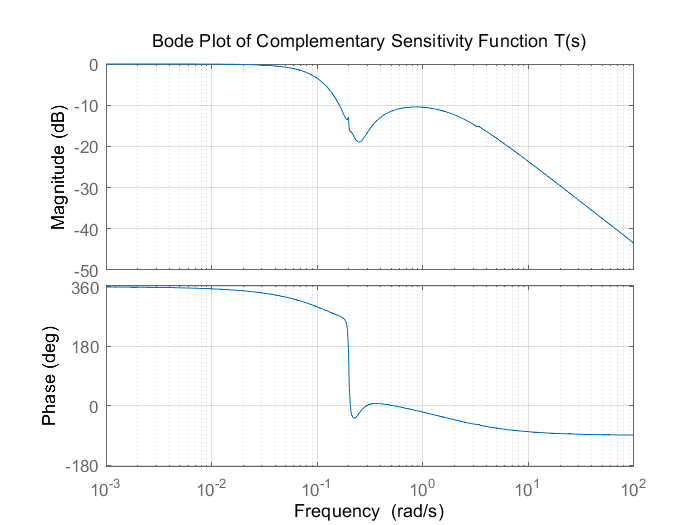

w = logspace(-3, 2, 500);
figure;
bode(complementary_sensitivity_function,w);
grid on;
title('Bode Plot of Complementary Sensitivity Function T(s)');

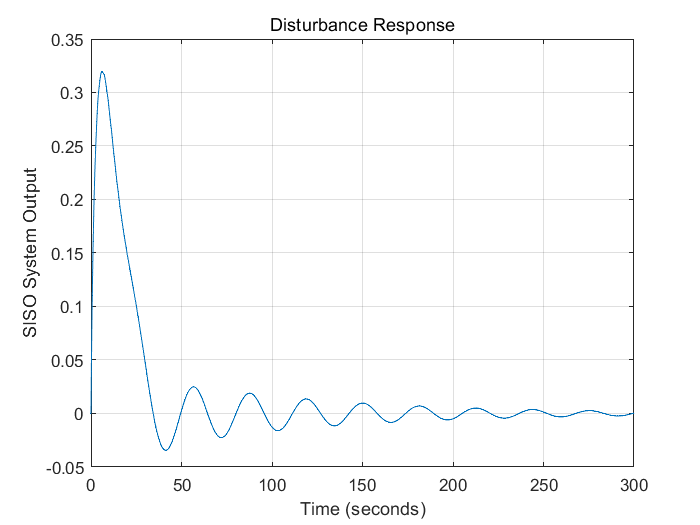

B_disturbance = B(:, 3);
C_output = C(1, :);      
D_disturbance = D(1, 3); 
Gd = ss(A, B_disturbance, C_output, D_disturbance); 
t = 0:0.1:300; 

disturbance_to_output = sensitivity_function * Gd;

disturbance = ones(size(t)); 
[y_disturbance, ~, ~] = lsim(disturbance_to_output, disturbance, t); 

figure;
plot(t, y_disturbance);
grid on;
xlabel('Time (seconds)');
ylabel('SISO System Output');
title('Disturbance Response');


info_disturbance = stepinfo(y_disturbance, t, disturbance(end));
disp(['Settling Time (Disturbance): ', num2str(info_disturbance.SettlingTime), ' seconds']);

Settling Time (Disturbance): NaN seconds


disp(['Overshoot (Disturbance): ', num2str(info_disturbance.Overshoot), ' %']);

Overshoot (Disturbance): 0 %



steady_state_value = y_disturbance(end); 
steady_state_error = abs(0 - steady_state_value); 
disp(['Steady-State Error (Disturbance): ', num2str(steady_state_error)]);

Steady-State Error (Disturbance): 0.00033442


sys_mimo = FWT(1:2, 1:2);
omega_1 = 0; 
omega_2 = 0.3 * 2 * pi; 
G_omega1 = freqresp(sys_mimo, omega_1); 
G_omega2 = freqresp(sys_mimo, omega_2); 
RGA_omega1 = G_omega1 .* (inv(G_omega1).'); 
RGA_omega2 = G_omega2 .* (inv(G_omega2).'); 

disp('RGA at ω = 0:');

RGA at ω = 0:


disp(RGA_omega1);

   -0.6554    1.6554
    1.6554   -0.6554




disp('RGA at ω = 0.3 * 2π:');

RGA at ω = 0.3 * 2π:


disp(RGA_omega2);

  -0.0283 + 0.1398i   1.0283 - 0.1398i
   1.0283 - 0.1398i  -0.0283 + 0.1398i



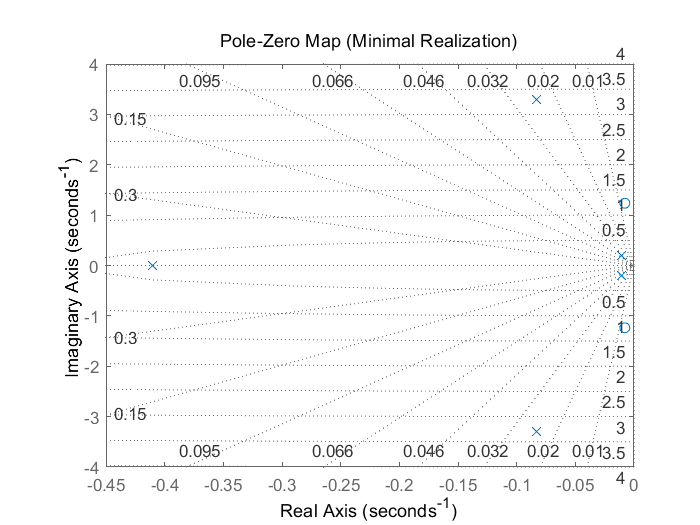


figure;
pzmap(sys_mimo);
grid on;
title('Pole-Zero Map (Minimal Realization)');

s = tf('s');
G = FWT(1:2, 1:2);
A = 1e-4;    
M = 3;     
wB = 0.3 * 2 * pi;   

Wp = [(s/M + wB)/(s + wB*A) 0; 0 0.05];
Wu = [0.005, 0;
      0, tf([5e-3, 7e-4, 5e-5], [1, 14e-4, 1e-6])];

Wt = [];
systemnames = 'G Wp Wu'; 
inputvar = '[w(2); u(2)]'; 
input_to_G = '[u]';       
input_to_Wu = '[u]';           
input_to_Wp = '[w-G]';    
outputvar = '[Wp; Wu; -G+w]'; 
sysoutname = 'P'; 
sysic;           
P = minreal(P);
[K2, CL2, GAM2, INFO2] = hinfsyn(P, 2, 2); 
controller_states = order(K2);
disp(['Number of States in Controller: ', num2str(controller_states)]);

Number of States in Controller: 8



plant_states = order(P);
disp(['Number of States in Generalized Plant: ', num2str(plant_states)]);

Number of States in Generalized Plant: 8


L_S=eye(2)+sys_mimo*K2;
L_n=L_S(1,1) * L_S(2,2) - L_S(1,2) * L_S(2,1);
N_n=minreal(L_n);

44 states removed.


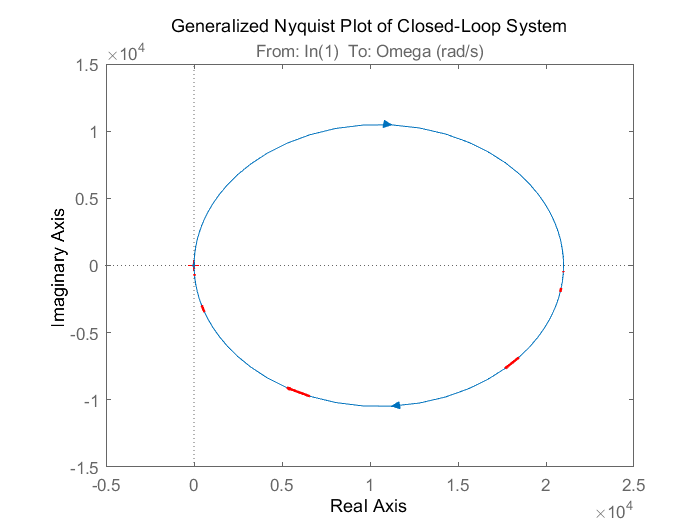


figure; 
nyquist(N_n); 
title('Generalized Nyquist Plot of Closed-Loop System');

[real_part, imag_part, ~] = nyquist(N_n); 
real_part = squeeze(real_part);  
imag_part = squeeze(imag_part);

hold on;
for k = 1:10:length(real_part)-1 
    u = real_part(k+1) - real_part(k); 
    v = imag_part(k+1) - imag_part(k); 

    quiver(real_part(k), imag_part(k), u, v, 0, 'r', 'MaxHeadSize', 0.5, 'LineWidth', 1.5);
end
hold off;


G_open = G*K2;
G_open=minreal(G_open);

5 states removed.


poles = pole(G_open);
disp(poles);

 -26.4187 + 0.0000i
   0.0007 + 3.3316i
   0.0007 - 3.3316i
  -0.0133 + 0.2018i
  -0.0133 - 0.2018i
  -0.0002 + 0.0000i
  -0.0688 + 0.0708i
  -0.0688 - 0.0708i



disp('Designed H∞ Controller (K2):');

Designed H∞ Controller (K2):


disp(K2);

  2×2 ss 数组 - 属性:

                A: [8×8 double]
                B: [8×2 double]
                C: [2×8 double]
                D: [2×2 double]
                E: []
           Scaled: 0
        StateName: {8×1 cell}
        StateUnit: {8×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [2×1 double]
      OutputDelay: [2×1 double]
               Ts: 0
         TimeUnit: 'seconds'
        InputName: {2×1 cell}
        InputUnit: {2×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {2×1 cell}
       OutputUnit: {2×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
     SamplingGrid: [1×1 struct]



disp(['Achieved H∞ Norm (GAM2): ', num2str(GAM2)]);

Achieved H∞ Norm (GAM2): 0.51315


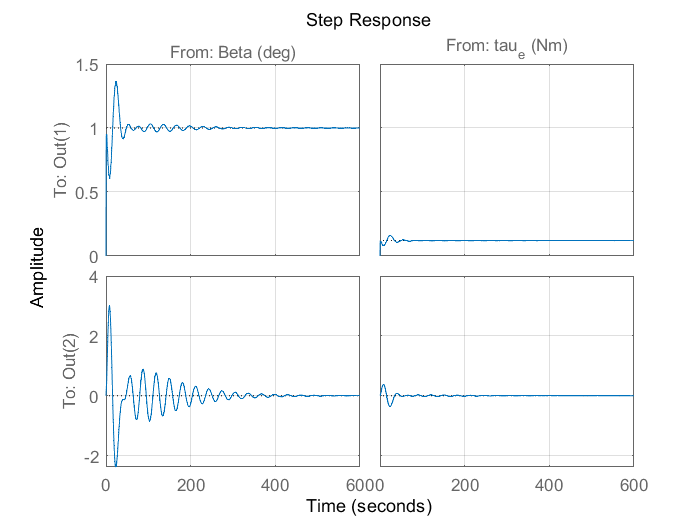

t = 0:0.1:300;
step_input = ones(size(t));
step_input_mimo = ones(length(t), 2); 
[y_siso_ref, ~, ~] = lsim(closed_loop, step_input, t);
closed_loop_2 = feedback(K2 * G, eye(2));
figure;
step(closed_loop_2);
grid;

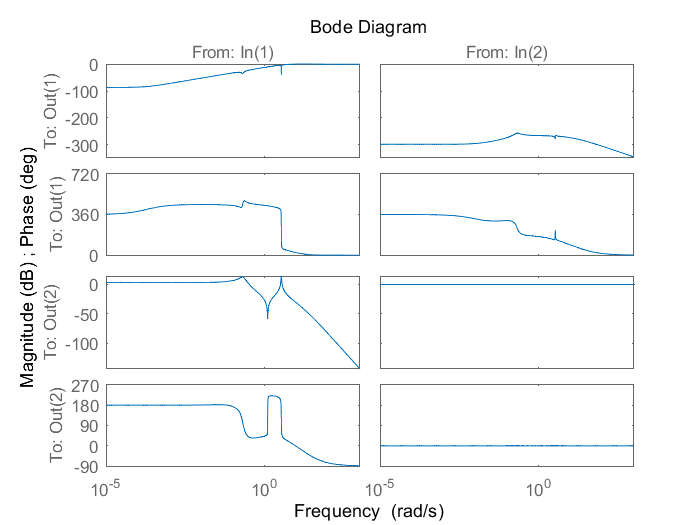

sensitivity_function_hinf = feedback(eye(size(G, 1)), G * K2);
figure; 
bode(sensitivity_function_hinf);

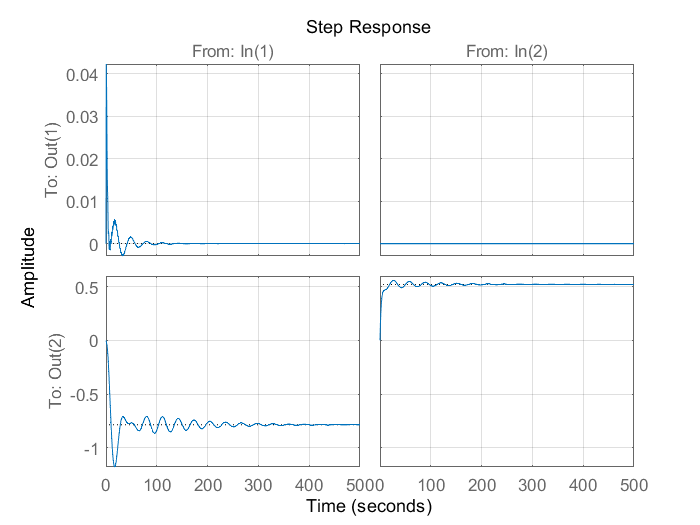


disturbance = ones(size(t));
disturbance_mimo = ones(length(t), 2);
[y_siso_disturbance, ~, ~] = lsim(sensitivity_function * Gd, disturbance, t);
[y_hinf_disturbance, ~, ~] = lsim(sensitivity_function_hinf * Gd, disturbance_mimo, t);
y_hinf_dis= sensitivity_function_hinf * Gd;
figure;
step(sensitivity_function_hinf * Gd);
grid;

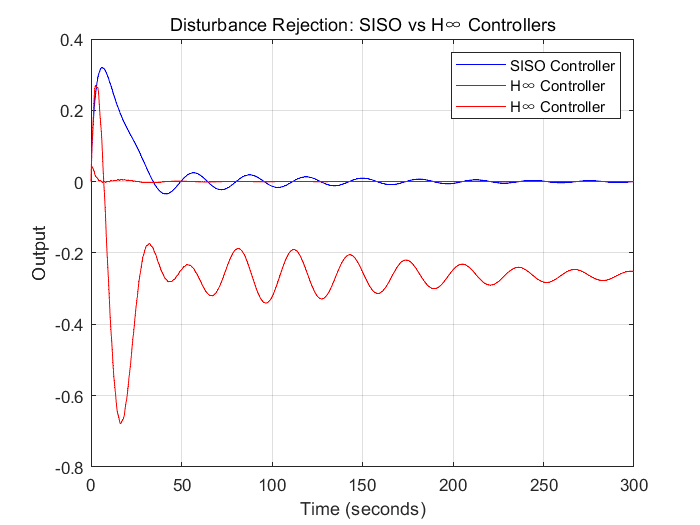


figure;
plot(t, y_siso_disturbance, 'b', 'DisplayName', 'SISO Controller');
hold on;
plot(t, y_hinf_disturbance, 'r', 'DisplayName', 'H∞ Controller');
grid on;
xlabel('Time (seconds)');
ylabel('Output');
legend;
title('Disturbance Rejection: SISO vs H∞ Controllers');

disp(['SISO Disturbance Settling Time: ', num2str(stepinfo(y_siso_disturbance, t).SettlingTime)]);

SISO Disturbance Settling Time: 182.7953


disp(['H∞ Disturbance Settling Time: ', num2str(stepinfo(y_hinf_disturbance, t).SettlingTime)]);

H∞ Disturbance Settling Time: 65.1562662316471090662162168882787227630615234375


disp(['SISO Steady-State Error (Disturbance): ', num2str(abs(0 - y_siso_disturbance(end)))]);

SISO Steady-State Error (Disturbance): 0.00033442


disp(['H∞ Steady-State Error (Disturbance): ', num2str(abs(0 - y_hinf_disturbance(end)))]);

H∞ Steady-State Error (Disturbance): 0.25176



s = tf('s'); 

Wp_simple = 0.95 * (s + 0.04*pi) / (0.016*pi + s);

Kp = realp('Kp', 1);  
Ki = realp('Ki', 1);
Kd = realp('Kd', 1);
Tf = realp('Tf', 1);

C_struct = Kp + Ki/s + (Kd*s) / (Tf*s + 1);

G_siso =  siso_sys; 
G_siso.u = 'u';          
G_siso.y = 'y_plant';    

Wp_siso = Wp_simple;
Wp_siso.u = 'y_act';     
Wp_siso.y = 'z1';        

C_siso = C_struct;
C_siso.u = 'e';         
C_siso.y = 'u';          

Sum1 = sumblk('e = w_ref - y_plant');  
Sum2 = sumblk('y_act = w_ref - y_plant'); 

Siso_Con = connect(G_siso, Wp_siso, C_siso, Sum1, Sum2, {'w_ref'}, {'y_plant', 'z1'});

opt = hinfstructOptions('Display', 'final', 'RandomStart', 5); 
N_siso = hinfstruct(Siso_Con, opt);

Final: Peak gain = 1.17, Iterations = 57
Final: Peak gain = 1.17, Iterations = 40
Final: Peak gain = 1.17, Iterations = 41
Final: Peak gain = 1.16, Iterations = 80
Final: Peak gain = 1.21, Iterations = 39
Final: Peak gain = 1.18, Iterations = 75



Kp_opt = N_siso.Blocks.Kp.Value;
Ki_opt = N_siso.Blocks.Ki.Value;
Kd_opt = N_siso.Blocks.Kd.Value;
Tf_opt = N_siso.Blocks.Tf.Value;

Kfb_opt = Kp_opt + Ki_opt/s + (Kd_opt*s) / (Tf_opt*s + 1);

disp(['Optimized Kp: ', num2str(Kp_opt)]);

Optimized Kp: 1.2873


disp(['Optimized Ki: ', num2str(Ki_opt)]);

Optimized Ki: 0.73756


disp(['Optimized Kd: ', num2str(Kd_opt)]);

Optimized Kd: 17.9429


disp(['Optimized Tf: ', num2str(Tf_opt)]);

Optimized Tf: 7.901e-08


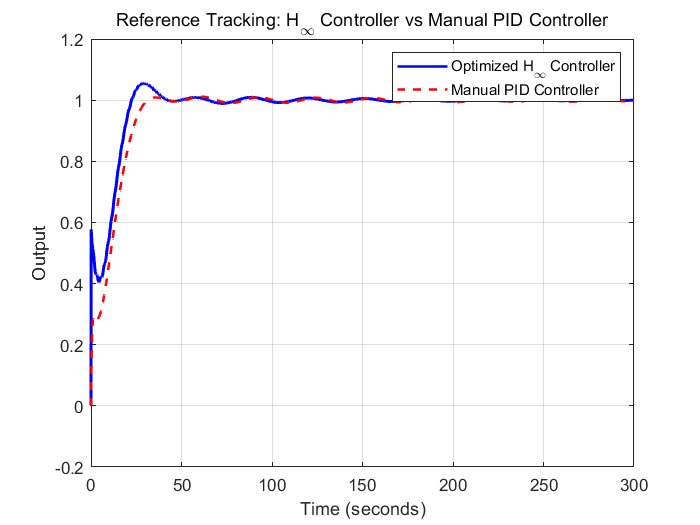


t = 0:0.1:300;  
step_input = ones(size(t));  

closed_loop_siso = feedback(Kfb_opt * G_siso, 1);
[y_pid, ~, ~] = lsim(closed_loop_siso, step_input, t);

[y_manual, ~, ~] = lsim(closed_loop, step_input, t);

figure;
plot(t, y_pid, 'b', 'LineWidth', 1.5);
hold on;
plot(t, y_manual, 'r--', 'LineWidth', 1.5);
grid on;
legend('Optimized H_\infty Controller', 'Manual PID Controller');
xlabel('Time (seconds)');
ylabel('Output');
title('Reference Tracking: H_\infty Controller vs Manual PID Controller');

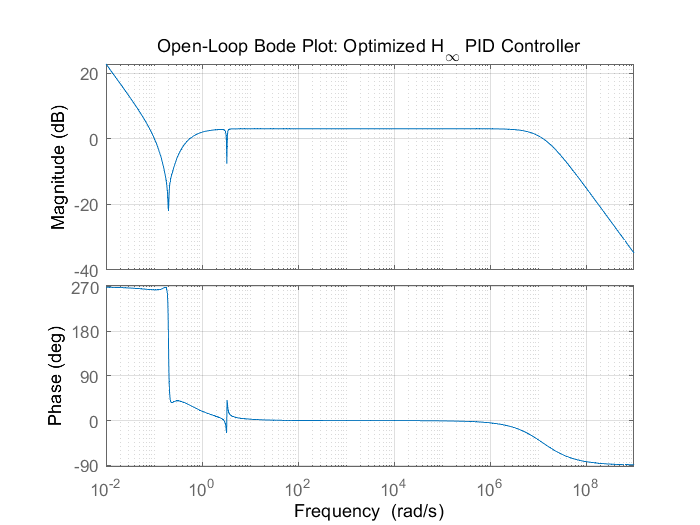


open_loop_pid = Kfb_opt * siso_sys;

figure;
bode(open_loop_pid);
grid on;
title('Open-Loop Bode Plot: Optimized H_\infty PID Controller');

[GM, PM, Wcg, Wcp] = margin(open_loop_pid);
disp(['Gain Margin (dB): ', num2str(20*log10(GM))]);

Gain Margin (dB): 21.8907


disp(['Phase Margin (degrees): ', num2str(PM)]);

Phase Margin (degrees): 83.8332


disp(['Gain Crossover Frequency (rad/s): ', num2str(Wcg)]);

Gain Crossover Frequency (rad/s): 0.19907


disp(['Phase Crossover Frequency (rad/s): ', num2str(Wcp)]);

Phase Crossover Frequency (rad/s): 0.10255



[mag, ~, omega] = bode(open_loop_pid);
mag = squeeze(mag);
omega = squeeze(omega);
mag_db = 20*log10(mag);
index_bw = find(mag_db <= -3, 1, 'first'); 
bw = omega(index_bw);
disp(['Bandwidth: ', num2str(bw), ' rad/s']);

Bandwidth: 0.12384 rad/s


info = stepinfo(closed_loop_siso);
disp(['Settling Time: ', num2str(info.SettlingTime), ' seconds']);

Settling Time: 37.5813 seconds


disp(['Overshoot: ', num2str(info.Overshoot), ' %']);

Overshoot: 5.5727 %


steady_state_value = dcgain(closed_loop_siso); 
steady_state_error = abs(1 - steady_state_value); 
disp(['Steady-State Error: ', num2str(steady_state_error)]);

Steady-State Error: 0


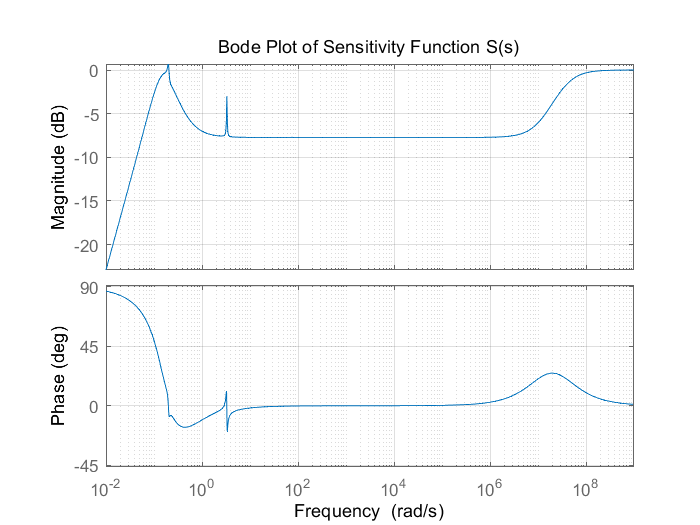


sensitivity_function = 1 / (1 + open_loop_pid);

complementary_sensitivity_function = open_loop_pid / (1 + open_loop_pid);

figure;
bode(sensitivity_function);
grid on;
title('Bode Plot of Sensitivity Function S(s)');

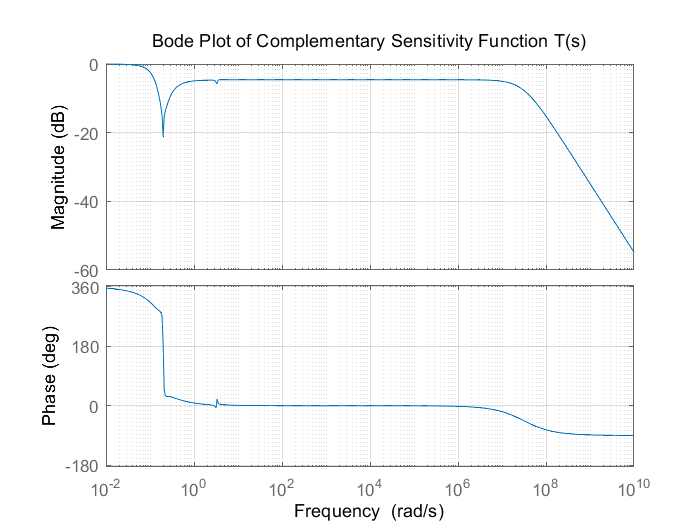

w = logspace(-2, 10, 500);
figure;
bode(complementary_sensitivity_function,w);
grid on;
title('Bode Plot of Complementary Sensitivity Function T(s)');

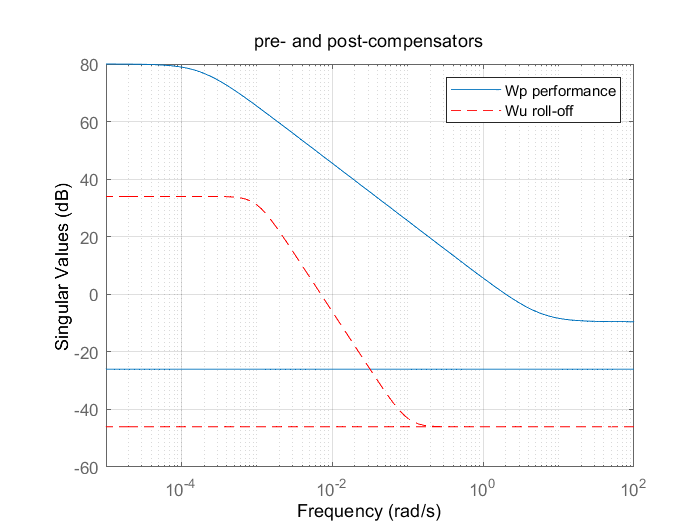

sigma(Wp,Wu,'r--'); grid; legend('Wp performance','Wu roll-off');
title('pre- and post-compensators');

Kp1 = realp('Kp1', 1);  
Ki1 = realp('Ki1', 1);
Kd1 = realp('Kd1', 1);
Tf1 = realp('Tf1', 1);
C_struct1 = Kp1 + Ki1/s + (Kd1*s) / (Tf1*s + 1);
Kp2 = realp('Kp2', 1);  
Ki2 = realp('Ki2', 1);
Kd2 = realp('Kd2', 1);
Tf2 = realp('Tf2', 1);
C_struct2 = Kp2 + Ki2/s + (Kd2*s) / (Tf2*s + 1);

K_mimo = [C_struct1 0; C_struct2 0];
G_mimo =  sys_mimo; 
G_mimo.u = 'u1';          
G_mimo.y = 'y1';    

Wp_mimo = Wp;
Wp_mimo.u = 'e1';     
Wp_mimo.y = 'z1';

Wu_mimo = Wu;
Wu_mimo.u = 'u1';     
Wu_mimo.y = 'z2'; 

C_mimo = K_mimo;
C_mimo.u = 'e1';         
C_mimo.y = 'u1';          

Sum1 = sumblk('e1 = w - y1',2); 
Mimo_Con = connect(G_mimo, Wp_mimo, Wu_mimo, C_mimo, Sum1, {'w'}, {'z1', 'z2'});
size(Mimo_Con)

Generalized state-space model with 4 outputs, 2 inputs, 20 states, and 8 blocks.


opt = hinfstructOptions('Display', 'final', 'RandomStart', 5);
[K_opt_mimo, gamma, info] = hinfstruct(Mimo_Con, opt);

Final: Peak gain = 1.95, Iterations = 114
Final: Peak gain = 1.27, Iterations = 301
Final: Peak gain = 1.94, Iterations = 114
Final: Peak gain = 1.95, Iterations = 100
Final: Peak gain = 1.94, Iterations = 255
Final: Peak gain = 11.3, Iterations = 46


disp(K_opt_mimo.Blocks);

    Kd1: [1×1 realp]
    Kd2: [1×1 realp]
    Ki1: [1×1 realp]
    Ki2: [1×1 realp]
    Kp1: [1×1 realp]
    Kp2: [1×1 realp]
    Tf1: [1×1 realp]
    Tf2: [1×1 realp]



disp(['Achieved H∞ Norm: ', num2str(gamma)]);

Achieved H∞ Norm: 1.2748


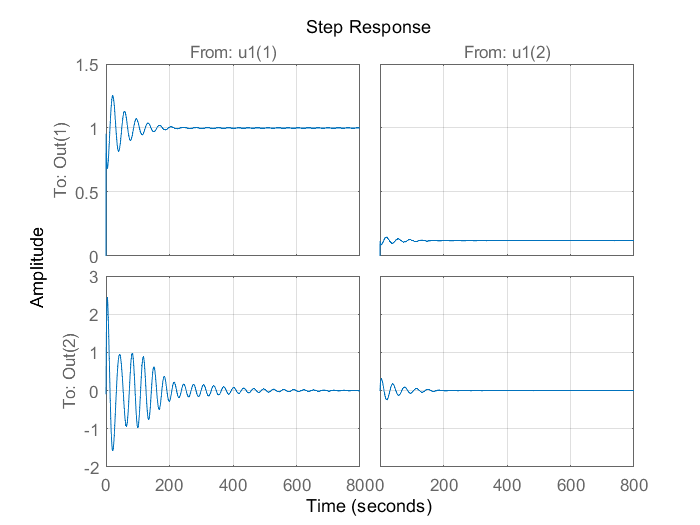

Kp1_opt = K_opt_mimo.Blocks.Kp1.Value;
Ki1_opt = K_opt_mimo.Blocks.Ki1.Value;
Kd1_opt = K_opt_mimo.Blocks.Kd1.Value;
Tf1_opt = K_opt_mimo.Blocks.Tf1.Value;

Kp2_opt = K_opt_mimo.Blocks.Kp2.Value;
Ki2_opt = K_opt_mimo.Blocks.Ki2.Value;
Kd2_opt = K_opt_mimo.Blocks.Kd2.Value;
Tf2_opt = K_opt_mimo.Blocks.Tf2.Value;
C1_opt = Kp1_opt + Ki1_opt/s + (Kd1_opt * s) / (Tf1_opt * s + 1);
C2_opt = Kp2_opt + Ki2_opt/s + (Kd2_opt * s) / (Tf2_opt * s + 1);

Kfb_opt_mimo = [C1_opt, 0; C2_opt, 0]; 

closed_loop_mimo = feedback(Kfb_opt_mimo * G_mimo, eye(2));
figure;
step(closed_loop_mimo);
grid;

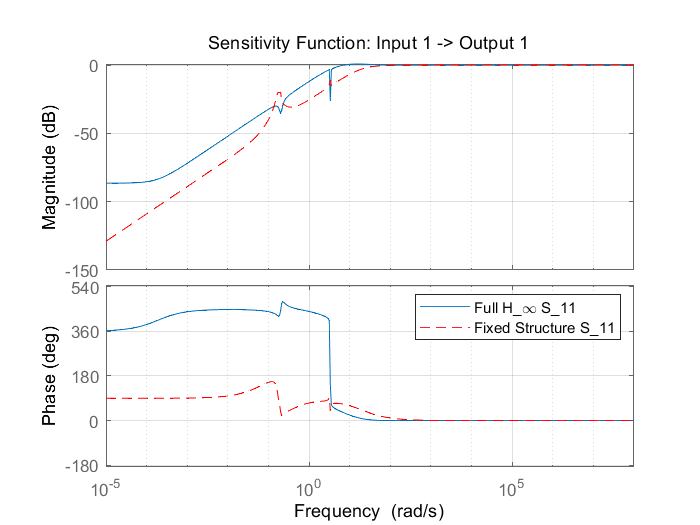

S_hinf = feedback(eye(size(G, 1)), G * K2);  
T_hinf = feedback(G * K2, eye(size(G, 1)));  

S_fixed = feedback(eye(2), G_mimo * Kfb_opt_mimo);
T_fixed = feedback(G_mimo * Kfb_opt_mimo, eye(2));

omega = logspace(-5, 8, 500);

S_hinf_11 = S_hinf(1, 1); % Input 1 -> Output 1
S_hinf_21 = S_hinf(2, 1); % Input 1 -> Output 2

S_fixed_11 = S_fixed(1, 1); % Input 1 -> Output 1
S_fixed_21 = S_fixed(2, 1); % Input 1 -> Output 2

T_hinf_11 = T_hinf(1, 1); % Input 1 -> Output 1
T_hinf_21 = T_hinf(2, 1); % Input 1 -> Output 2

T_fixed_11 = T_fixed(1, 1); % Input 1 -> Output 1
T_fixed_21 = T_fixed(2, 1); % Input 1 -> Output 2

figure;
bode(S_hinf_11, omega);
hold on;
bode(S_fixed_11, omega, 'r--');
grid on;
legend('Full H_\infty S_{11}', 'Fixed Structure S_{11}');
title('Sensitivity Function: Input 1 -> Output 1');

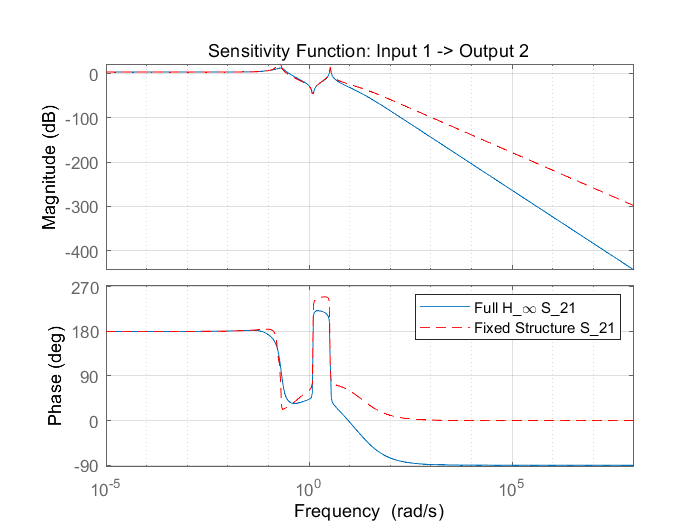

figure;
bode(S_hinf_21, omega);
hold on;
bode(S_fixed_21, omega, 'r--');
grid on;
legend('Full H_\infty S_{21}', 'Fixed Structure S_{21}');
title('Sensitivity Function: Input 1 -> Output 2');

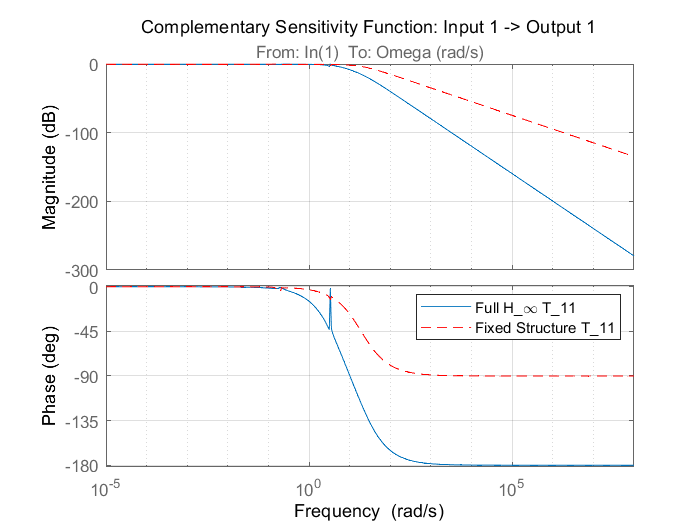

figure;
bode(T_hinf_11, omega);
hold on;
bode(T_fixed_11, omega, 'r--');
grid on;
legend('Full H_\infty T_{11}', 'Fixed Structure T_{11}');
title('Complementary Sensitivity Function: Input 1 -> Output 1');

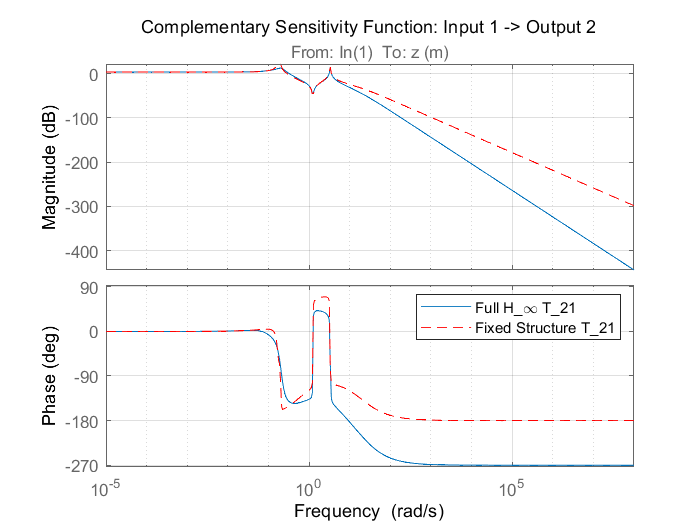

figure;
bode(T_hinf_21, omega);
hold on;
bode(T_fixed_21, omega, 'r--');
grid on;
legend('Full H_\infty T_{21}', 'Fixed Structure T_{21}');
title('Complementary Sensitivity Function: Input 1 -> Output 2');

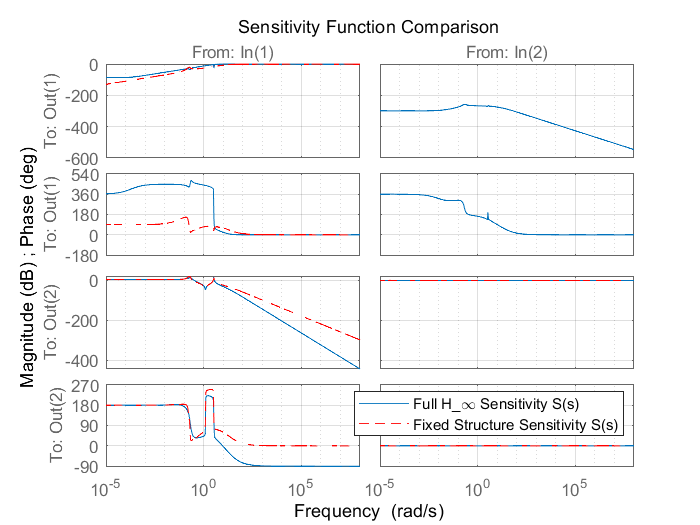

figure;
bode(S_hinf, omega);
hold on;
bode(S_fixed, omega, 'r--');
grid on;
legend('Full H_\infty Sensitivity S(s)', 'Fixed Structure Sensitivity S(s)');
title('Sensitivity Function Comparison');

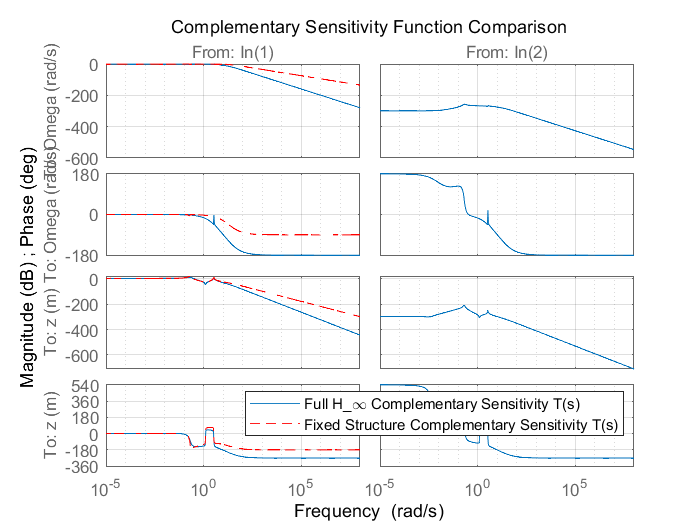

figure;
bode(T_hinf, omega);
hold on;
bode(T_fixed, omega, 'r--');
grid on;
legend('Full H_\infty Complementary Sensitivity T(s)', 'Fixed Structure Complementary Sensitivity T(s)');
title('Complementary Sensitivity Function Comparison');

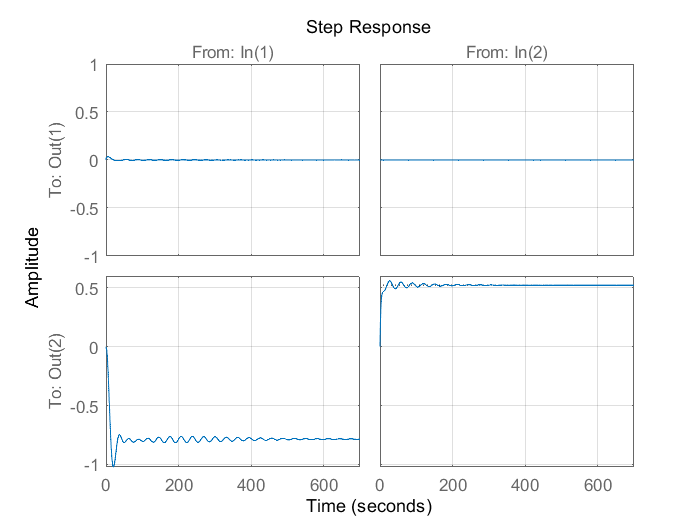

disturbance_mimo = ones(length(t), 2);
[y_fixed_disturbance, ~, ~] = lsim(S_fixed * Gd, disturbance_mimo, t);
y_fixed_dis=S_fixed * Gd;

% y_hinf_dis_11 = y_hinf_dis(1, 1); % Input 1 -> Output 1
% y_hinf_dis_21 = y_hinf_dis(2, 1); % Input 1 -> Output 2
% y_fixed_dis_11 = y_fixed_dis(1, 1); % Input 1 -> Output 1
% y_fixed_dis_21 = y_fixed_dis(2, 1); % Input 1 -> Output 2
% figure;
% step(y_hinf_dis_11);
% hold on;
% step(y_fixed_dis_11, 'r--');
% grid on;
% legend('Full H_\infty', 'Fixed Structure');
% title('Disturbace rejection: Input 1 -> Output 1');
% 
% figure;
% step(y_hinf_dis_21);
% hold on;
% step(y_fixed_dis_21, 'r--');
% grid on;
% legend('Full H_\infty', 'Fixed Structure');
% title('Disturbace rejection: Input 1 -> Output 2');

figure;
step(S_fixed * Gd);
grid;

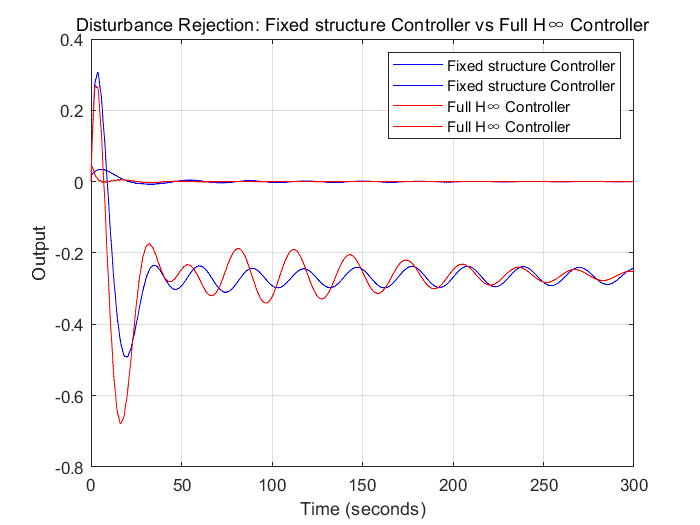


figure;
plot(t, y_fixed_disturbance, 'b', 'DisplayName', 'Fixed structure Controller');
hold on;
plot(t, y_hinf_disturbance, 'r', 'DisplayName', 'Full H∞ Controller');
grid on;
xlabel('Time (seconds)');
ylabel('Output');
legend;
title('Disturbance Rejection: Fixed structure Controller vs Full H∞ Controller');